## Problem 1

%Running sum order 3
hRS1 = [1,1,1,1]

hRS1 =      1     1     1     1


syms z
HRS1 = z^0 + z^(-1)+z^(-2)+z^(-3);
HRS1_2 = HRS1*z^3

$$HRS1\_2 = z^{3}\,\left(\frac{1}{z}+\frac{1}{z^{2}}+\frac{1}{z^{3}}+1\right)$$

poles1 = roots([1,0,0,0])

poles1 =      0
     0
     0


zeroes1 =roots([1,1,1,1])

zeroes1 =   -1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i



hRS1 = [1,1,1,1,1,1];
HRS2 = z^0 + z^(-1)+z^(-2)+z^(-3) + z^(-4)+z^(-5);
HRS2_1 = z^5*HRS2

$$HRS2\_1 = z^{5}\,\left(\frac{1}{z}+\frac{1}{z^{2}}+\frac{1}{z^{3}}+\frac{1}{z^{4}}+\frac{1}{z^{5}}+1\right)$$

poles2 = roots([1,0,0,0,0,0])

poles2 =      0
     0
     0
     0
     0


zeroes2 = roots([1,1,1,1,1,1])

zeroes2 =    0.5000 + 0.8660i
   0.5000 - 0.8660i
  -1.0000 + 0.0000i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i


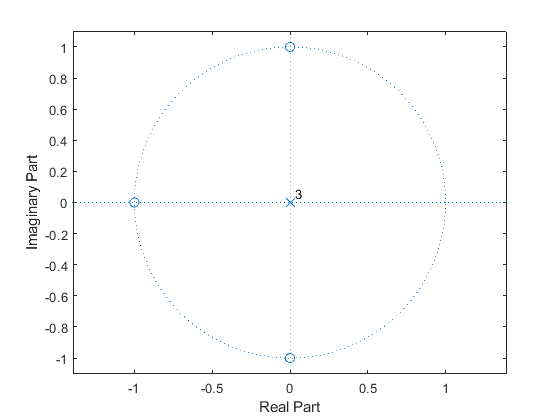


zplane(zeroes1,poles1)

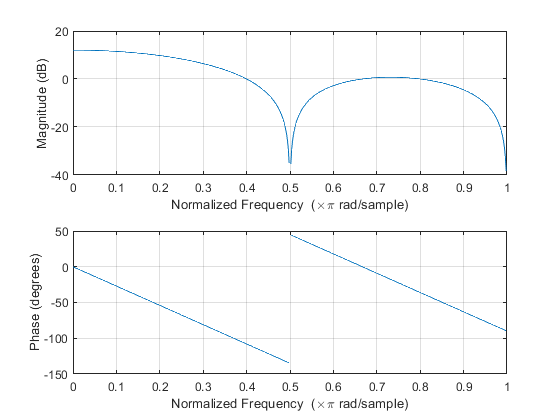

freqz([1,1,1,1],[1,0,0,0])

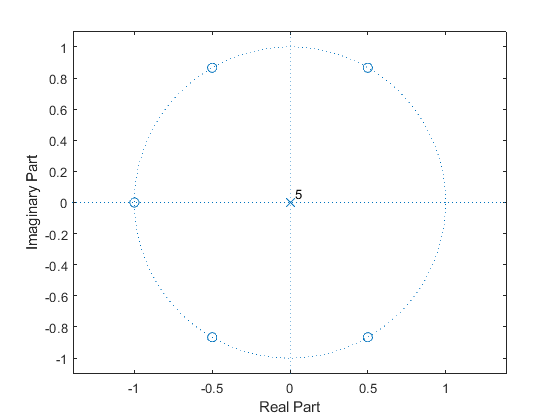

zplane(zeroes2,poles2)

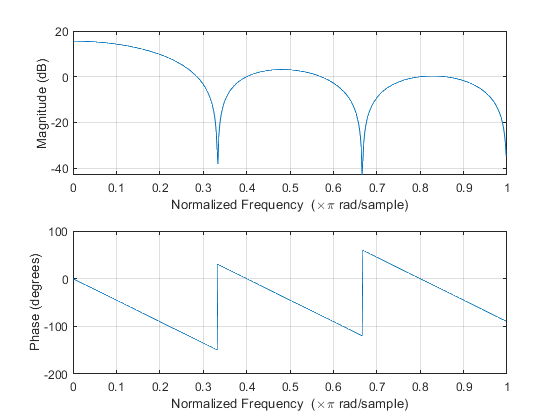

freqz([1,1,1,1,1,1],[1,0,0,0,0,0])


%-------------------------------------------------
num_poly = 1/4*[1,1,1,1];
den_poly = 1/4*[1,0,0,0];

num2_poly = 1/4*[1,1,1,1,1,1];
den2_poly = 1/4*[1,0,0,0,0,0];

freqz(num_poly,den_poly)

freqz(num2_poly,den2_poly)

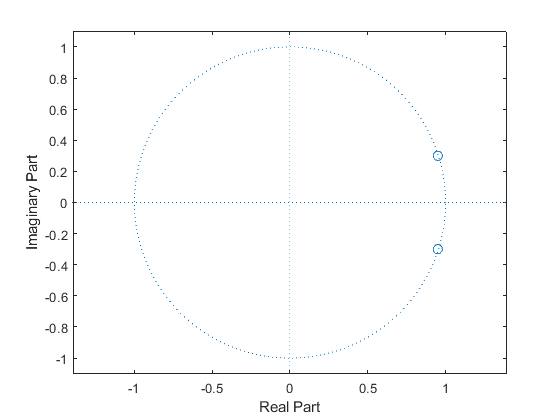

%The frequencies that are attenuated can be amplified if you replace the
%zeroes with the poles.
z1 = [0.95+i*0.3;0.95-i*0.3];
zplane(z1)

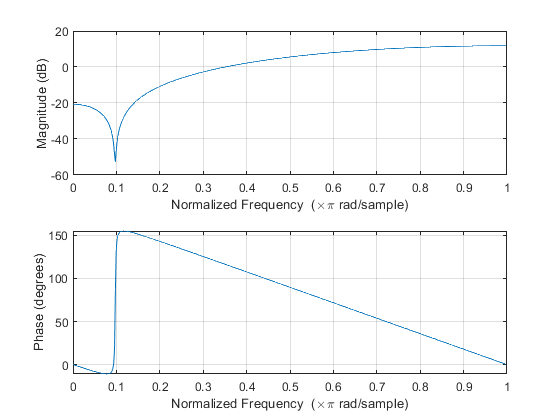

freqz([1,-1.90,0.9925],[1])%Two zeroes

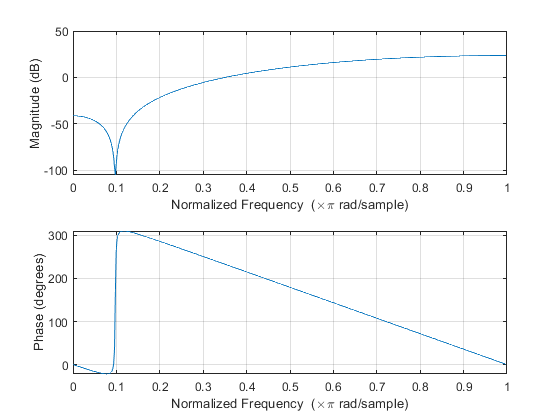

%Four zeroes
freqz([1,-3.8,5.5950,-3.7715,0.985056],[1])

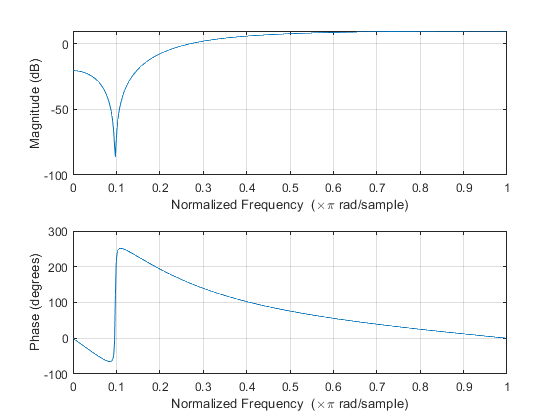

%z2 = 0.4755+0.15450
%Four poles added
freqz([1,-3.8,5.5950,-3.7715,0.985056],[1,-1.9020,1.4043,-0.47544,0.06248])

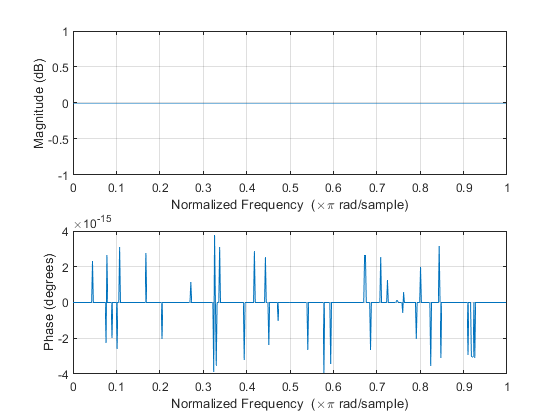

%The poles and zeroes negate each other the closer R gets to 1.
%If R = 1 -> the system just becomes a cable.
freqz([1,-3.8,5.5950,-3.7715,0.985056],[1,-3.8,5.5950,-3.7715,0.985056])

## Problem 1.2